# AuE-6600 | Dynamic Performance of Vehicles

## Bonus Problem 1

### Problem

When a vehicle is running on a wet surface, a hydroplaning phenomenon can easily occur when the speed of the vehicle reaches certain values. Such a condition is always extremely dangerous. Therefore, analyze the variation in the tire side force and the aligning torque when the hydroplaning phenomenon  occurs. (Assume the slip angle $\alpha$ is constant.)

Hint: You can follow and adapt the steps of the elastic lateral force model with parabolic pressure distribution as discussed in class and as practiced one by one. You should consider an area of waterskiing starting from the leading edge of the tire print and extending a length $l_w$ into the patch. In this waterskiing area zero adhesion can be assumed. 

Calculate the side force and the total aligning torque using the following parameters: 

- The vertical load is Fz = 4000 N

- Slip angle is 4 degrees

- Coefficient of friction is 0.6

- Length of the contact patch, 2a = 0.16 m

- Lateral stiffness of the rubber layer, Cy = 3.5 x 10^6 N/m^2 

The above calculation will depend on the length of the waterskiing area $l_w$. 

Produce the following plots: 

- Side force vs. waterskiing area in percent

- Total aligning torque vs. waterskiing area in percent

- Pneumatic trail vs. waterskiing area in percent.

Comment on the results. 

### Solution

1. Give limits on the Understeer Gradient, so that the characteristic velocity of a vehicle with wheelbase 3.1 m will be in the desired range of 80-120 km/h.

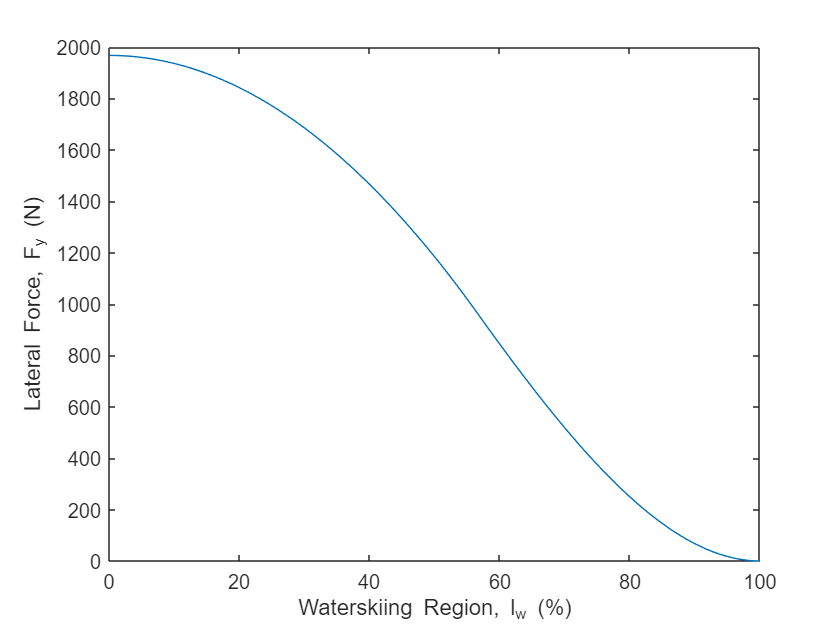

% Given
Fz = 4000; % N
SA = 4; % deg
SA = deg2rad(SA); % rad
u = 0.6;
a = 0.16/2; % m
cy = 3.5*1e6; % N/m^2
% Calculate Sy and xs
Sy = tan(SA);
theta = (2*a^2*cy)/(3*u*Fz);
xs = 2*a*(1-(theta*Sy));
% Vary lw and calculate Fy, Mz
Fy = [];
Mz = [];
e = [];
for lw = linspace(0,2*a,100)
    if lw < xs
        Fy(end+1) = (cy/(2*a*theta))*((-a*lw^2)-(xs^3/6)+((xs*lw^2)/2)+((4*a^3)/3));
        Mz(end+1) = (-cy/(2*a*theta))*(((-a*xs^3)/6)-(a^2*lw^2)+((2*a*lw^3)/3)+((a*xs*lw^2)/2)-((xs*lw^3)/3)+(xs^4/12));
    else
        Fy(end+1) = (cy/(2*a*theta))*(((4*a^3)/3)-(a*lw^2)+(lw^3/3));
        Mz(end+1) = (cy/(2*a*theta))*((a^2*lw^2)-(a*lw^3)+((lw^4)/4));
    end
end
% MATLAB has a small truncation error (of the order of 1e-13)
% So correct it (especially for exact zero value)
for i = 1:100
    if Fy(i) <= 1e-12
        Fy(i) = 0;
    end
    if Mz(i) <= 1e-12
        Mz(i) = 0;
    end
end
% Calculate e from Fy and Mz
e = Mz./Fy;
% Plots
lw = linspace(0,2*a,100);
plot((100*lw)/(2*a), Fy)
xlabel('Waterskiing Region, l_w (%)');
ylabel('Lateral Force, F_y (N)');

**Inference:**

When no part of the tire is undergoing hydroplaning, the tire is capable of producing lateral force to its full capacity (Fy due to sticking + sliding regions, considering parabolic pressure distribution). However, as the waterskiing region starts increasing, the region of tire patch that is undergoing hydroplaning cannot anymore contribute to produce lateral force, and as a result, the total lateral force produced by the tire starts dropping. Finally, when the entire patch is undergoing hydroplaning, the tire cannot produce any force, and as a result, the total lateral force drops to zero.

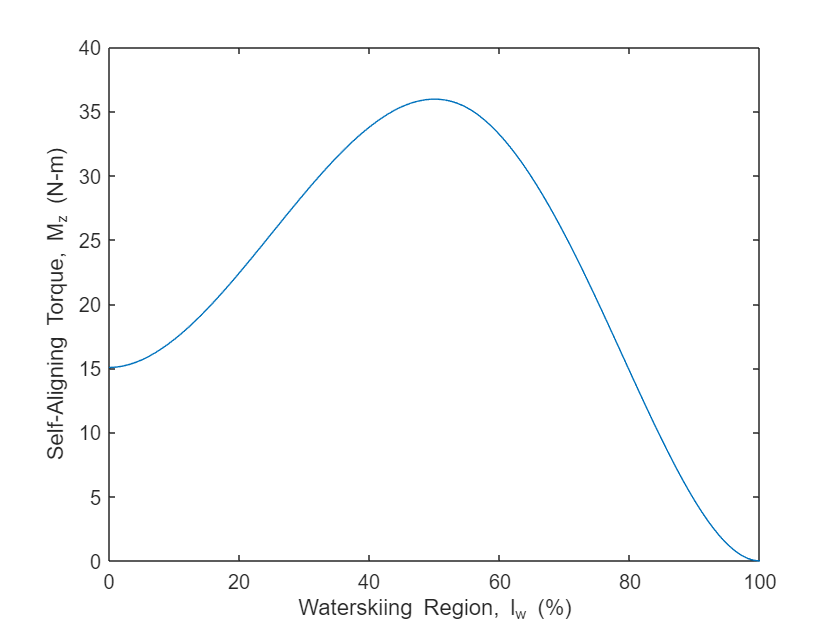

plot((100*lw)/(2*a), Mz)
xlabel('Waterskiing Region, l_w (%)');
ylabel('Self-Aligning Torque, M_z (N-m)');

**Inference:**

When no part of the tire is undergoing hydroplaning, the negative moments (in the region x=0 to x=a) oppose the positive moments (in the region x=a to x=2*a), but since the positive moments are greater in magnitude (because Fy is greater in magnitude in region x=a to x=2*a than in region x=0 to x=a), the total resultant moment is non-zero and has the sign of the moments in the region x=a to x=2*a (i.e. positive). As the waterskiing region starts increasing, the region of tire patch that is undergoing hydroplaning cannot anymore contribute to produce (negative) moments, and as a result, the total resultant moment starts increasing (since there is less opposing moment now). This happens till leading half of the tire is hydroplaning, this is when the moment is maximum (since there are no opposing moments at lw=a, but there are all the positive moments). After this point, the positive moments (in initial region after x=a) also stop contributing as that region undergoes hydroplaning, and as a result, the total resultant moment starts decreasing. Finally, when the entire patch is undergoing hydroplaning, the tire cannot produce any force, and as a result, the total self-aligning moment drops to zero.

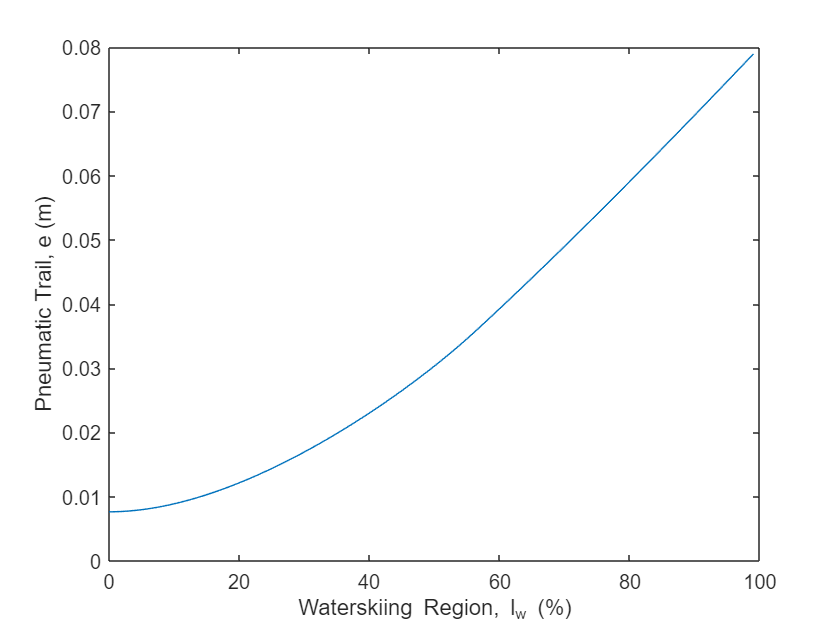

plot((100*lw)/(2*a), e)
xlabel('Waterskiing Region, l_w (%)');
ylabel('Pneumatic Trail, e (m)');

**Inference:**

When no part of the tire is undergoing hydroplaning, the resultant of lateral force is slightly towards the right of x=a (since forces between x=a and x=2*a have higher magnitude than forces between x=0 and x=a). As a result the pneumatic trail is the moment-arm at which the resultant Fy is acting. However, as the waterskiing region starts increasing, the region of tire patch that is undergoing hydroplaning cannot anymore contribute to produce lateral force, and as a result, the total lateral force produced by the tire starts shifting right-wards. This causes the moment-arm (a.k.a. pneumatic trail) to also start shifting right-wards, thus increasing its distance from center of the tire-patch. Penultimately, when the entire patch is just about to undergo hydroplaning, resultant Fy is nothing but the Fy due to last tread-element located at a distance of $\approx$a from center, which causes the moment-arm (a.k.a. pneumatic trail) to approach close to a=0.8 m in our case. However, finally, when the entire patch is undergoing hydroplaning, the tire cannot produce any force/self-aligning moment, and as a result, the pneumatic trail cannot be defined (it becomes of 0/0 form).